# Lattice Modulation, Scan Force

## Set atom and magnetic field

% atom
atom = Alkali("Lithium7");

% B field
bList = num2cell(linspace(1.164173e-2,1.3407113e-2,100));
niB = 543.6e-4; %non-interacting feshbach field
bField = cellfun(@(x) MagneticField(...
    bias = [0;0;niB],...
    gradient = [0,0,0;0,0,0;0,x,0]),bList,'UniformOutput',false);

## Set benchmark simulation

% set laser
laser = GaussianBeam( ...
    wavelength = 1064e-9,...
    direction = [0;1;0],...
    polarization = [0;0;1],...
    power = 0.6, ...
    waist = 110e-6 ...
    );
laser = {laser};

% set optical lattice
ol = OpticalLattice(atom,laser{1});
ol.DepthSpec = 8.5174 * ol.RecoilEnergy;
ol.updateIntensity;
laser = {ol.Laser};


% set modulation
pulse1 = TrapezoidalSinePulse( ...
    amplitude=0.035 * 4 * 2, ...
    duration=5e-3, ...
    frequency=121e3, ...
    startTime=0,riseTime=1e-4,fallTime=1e-4);
pulse2 = TrapezoidalSinePulse( ...
    amplitude=0.035 * 2, ...
    duration=8e-3, ...
    frequency=143.2231e3, ...
    startTime=5e-3,riseTime=1e-4,fallTime=1e-4);
latticeMod = WaveformList("LatticeMod");
latticeMod.WaveformOrigin = {pulse1,pulse2};
latticeMod.ConcatMethod = "Simultaneous";
% latticeMod.SamplingRate = 10e6;
latticeMod = {latticeMod};

ic = InitialCondition("SeSim1D");
se2 = LatticeSeSim1D("Test", ...
    laser = laser,...
    magneticField = bField,...
    latticeModulation = latticeMod,...
    timeStep=1e-7,...
    totalTime=13e-3,...
    spaceRange = 1000e-06,...
    spaceStep = 1e-8,initialCondition = ic);

Constructing the object.
Setting up folders.
Creating a database entry.
Updating the object file.



% initial condition
x = se2.SimRun(1).SpaceList;
x = x.';

sigma = 50e-6;
kL = ol.Laser.AngularWavenumber;
qIni = -kL;
% qmin = - kL;
% qmax =  kL;
% qList = linspace(qmin,qmax,5000);
% qList = qList(1:end-1);
% [~,qIdx] = min(abs(qList - qIni));
% [E,~,~,ck] = ol.computeBand1D(qList,0,x);
% % ck = ol.BlochStateFourier;
% vn = ck(:,2,qIdx).';
% vn = repmat(vn,numel(x),1);
% nmax = max(2 * 2+49,101);
% k = (1-nmax:2:nmax-1) * kL;
% k = repmat(k,numel(x),1);
% 
% temp = vn.* exp(1i*(k+qList(qIdx)).* x);
% phi = sum(temp,2);
[~,~,phi] = ol.computeBand1D(qIni,0,x);

psi = exp(-(x).^2 / 4 / sigma^2) .* phi;
ic.WaveFunction = psi;
for ii = 1:numel(se2.SimRun)
    se2.SimRun(ii).InitialCondition.WaveFunction = psi;
end

se2.start

## Plot

% plot benchmark
trialNumber = 21;
obj = loadTrial(createReader("simulation"),"lattice_schrodinger_equation_simulation_1d",trialNumber);
% obj.SimRun(1).showSpaceTime
nRun = numel(obj.SimRun);
freqList = zeros(1,nRun);
ampList = zeros(1,nRun);
for ii = 1:nRun
    rawData = obj.SimRun(ii).showPeak;
    fitData = SineFit1D(rawData);
    fitData.do;
    freqList(ii) = fitData.Coefficient(2);
    ampList(ii) = fitData.Coefficient(1);
end

## Analysis: animation

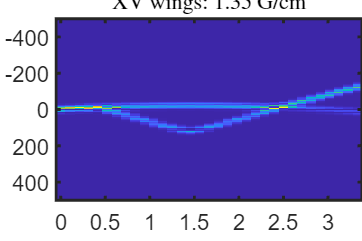

trialNumber = 21;
filename = "AI_Force_Scan.gif";
startDelay=.5;
midDelay=.1;
endDelay=.5;
obj = loadTrial(createReader("simulation"),"lattice_schrodinger_equation_simulation_1d",trialNumber);
nSpace = obj.SimRun(1).NSpaceStep;
nRun = numel(obj.SimRun);
psiList = zeros(nRun,nSpace);
psi1 = obj.SimRun(1).readRun("WaveFunction");
psi1 = psi1(1,:);
n1 = abs(psi1).^2;
nLim = max(n1);
for ii = 1:nRun
    psiList(ii,:) = obj.SimRun(ii).readRun("FinalWaveFunction");
    obj.SimRun(ii).showSpaceTime;
    fig = gcf;
    imgAxes = gca;
    imgAxes.CLim = [0,nLim];

    % Update title
    imgAxes.Title.String = "XV wings: $" + num2str(norm(bField{ii}.GradientLu)) + "~\mathrm{G/cm}$";
    imgAxes.Title.Interpreter = "latex";
    render

    % Save as gif
    frame = getframe(fig);
    im = frame2im(frame);
    [A,map] = rgb2ind(im,256);
    if ii == 1
        imwrite(A,map,filename,'gif','LoopCount',Inf,'DelayTime',startDelay);
    else
        if ii==nRun
            imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',endDelay);
        else
            imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',midDelay);
        end
    end
end

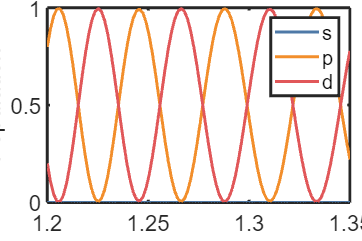

x = obj.SimRun(1).SpaceList;
bandPop = ol.computeBandPopulation1D(psiList,int32(2),x);
bListGauss = cell2mat(bList) * 1e2;
figure
plot(bListGauss,bandPop)
xlabel("XV wings field gradient [Gauss/cm]")
ylabel("Population")
legend("s","p","d")
render
saveas(gcf,"AI_Force_Scan","png")

trialNumber = 21;
obj = loadTrial(createReader("simulation"),"lattice_schrodinger_equation_simulation_1d",trialNumber);
